clear;      % Removes all variables from the workspace
clc;        % Clears the Command Window
close all;  % Closes any hidden or external figure windows

raw_data = load("identification_data\rod_2_identification\matlab.mat");

% Unpack the loaded data into struct
angles = 15:15:120;

for i = 1:length(angles)
    var_name = sprintf('theta_2_%d_degrees', angles(i));
    data = raw_data.(var_name);

    expData(i).t = data.Time;
    expData(i).y_raw = data.Data;
    expData(i).u = zeros(size(data.Time));
    expData(i).initial_angle = angles(i);
end

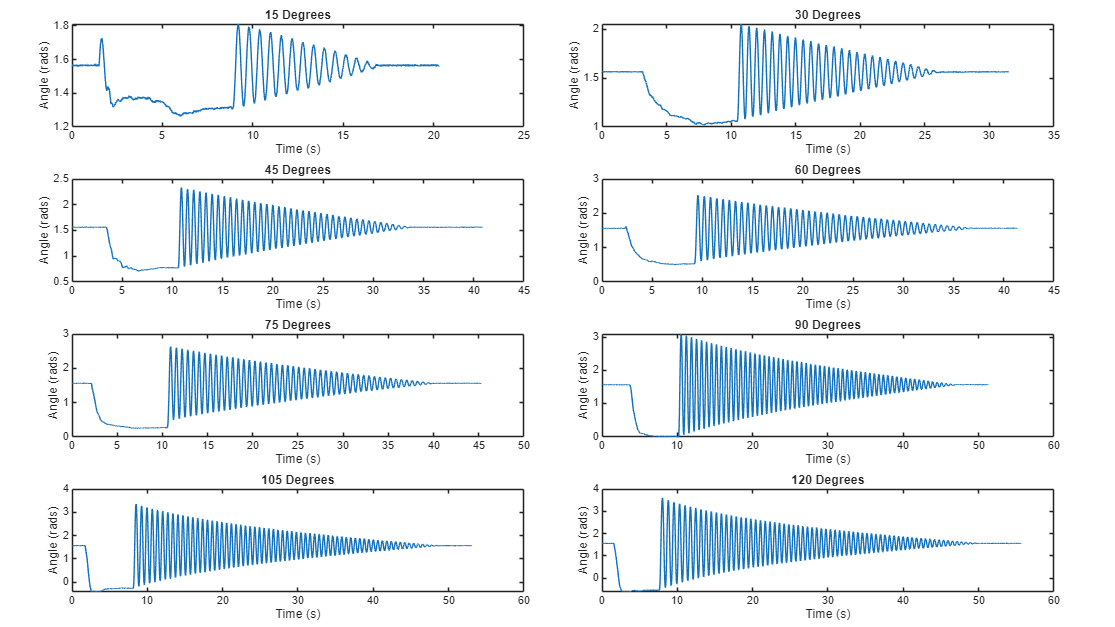

% Plotting raw data in time domain
figure('Units', 'normalized', 'Position', [0, 0, 1, 1]);
tiledlayout(4, 2, 'TileSpacing', 'compact', 'Padding', 'compact');

for i = 1:length(angles)
    nexttile;
    plot(expData(i).t, expData(i).y_raw, "DisplayName", "Raw Data");
    title(sprintf('%d Degrees', angles(i)));
    ylabel("Angle (rads)");
    xlabel("Time (s)");
end

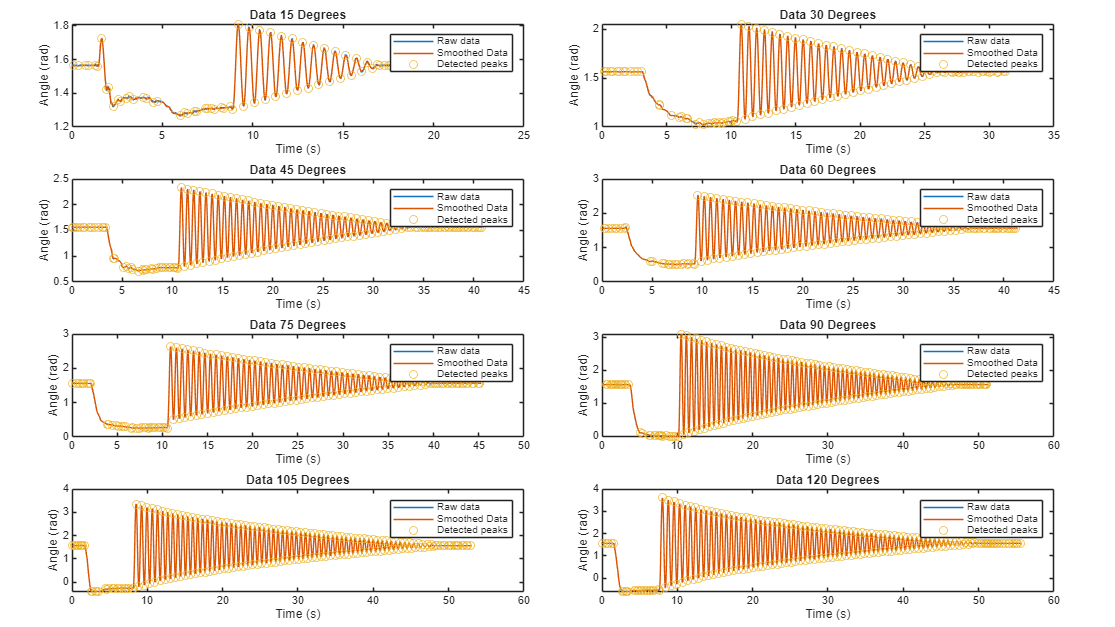

% Plot data with peak detection to truncate usefull data
figure('Units', 'normalized', 'Position', [0, 0, 1, 1]);
tiledlayout(4, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
for i = 1:length(angles)

    Ts = expData(i).t(2) - expData(i).t(1);
    fs = 1/Ts;

    % Filter out noise for peak detection
    fc = 5;     % Cut off frequency
    [b, a] = butter(3, fc/(fs/2), 'low');
    
    expData(i).y_smooth = filtfilt(b, a, expData(i).y_raw);

    % Find peaks
    minDist = round(0.3 * fs);
    [pMax, locMax] = findpeaks(expData(i).y_smooth, 'MinPeakDistance', minDist);
    [pMin, locMin] = findpeaks(-expData(i).y_smooth, 'MinPeakDistance', minDist);
    peak_indices = sort([locMax; locMin]);
    
    % Plot data with detected peaks
    nexttile;
    plot(expData(i).t, expData(i).y_raw, 'DisplayName', 'Raw data');
    hold on;
    plot(expData(i).t, expData(i).y_smooth, 'DisplayName', 'Smoothed Data');
    plot(expData(i).t(peak_indices), expData(i).y_smooth(peak_indices), 'o', 'DisplayName', 'Detected peaks');
    
    legend;
    title(sprintf('Data %d Degrees', angles(i)));
    xlabel('Time (s)');
    ylabel('Angle (rad)');
end

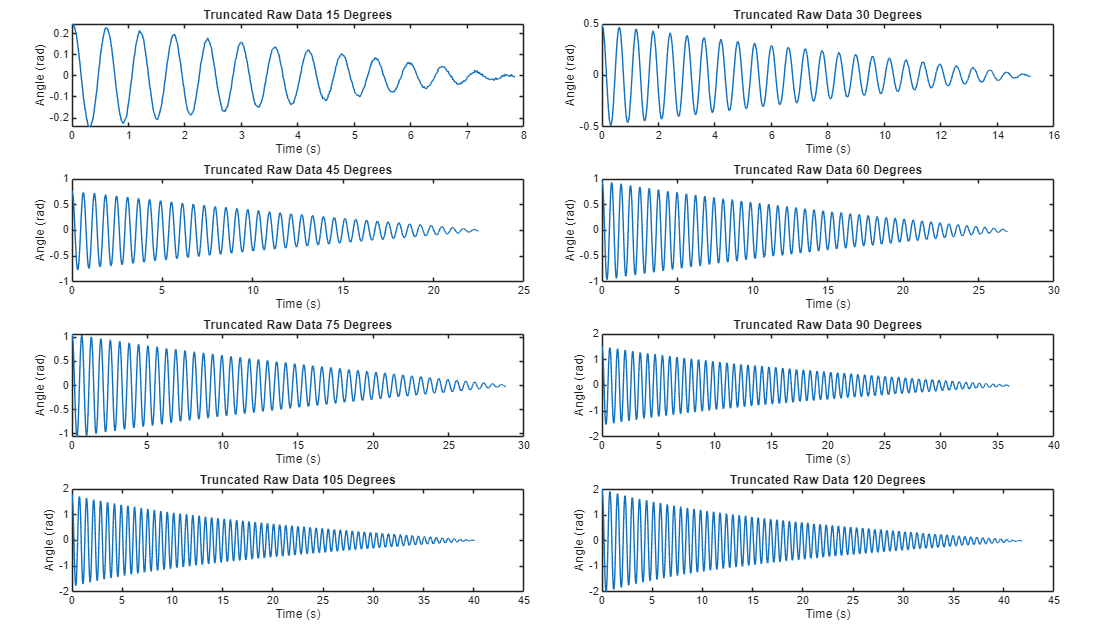

% Set indices for truncated data
expData(1).start_index = 919;
expData(1).end_index = 1703;

expData(2).start_index = 1078;
expData(2).end_index = 2594;

expData(3).start_index = 1089;
expData(3).end_index = 3339;

expData(4).start_index = 955;
expData(4).end_index = 3643;

expData(5).start_index = 1091;
expData(5).end_index = 3969;

expData(6).start_index = 1051;
expData(6).end_index = 4656;

expData(7).start_index = 851;
expData(7).end_index = 4857;

expData(8).start_index = 802;
expData(8).end_index = 4984;

for i = 1:length(angles)
    expData(i).y_id = expData(i).y_raw(expData(i).start_index:expData(i).end_index);
    expData(i).y_id = expData(i).y_id - mean(expData(i).y_raw(expData(i).end_index + 1:end));
    expData(i).t_id = expData(i).t(expData(i).start_index:expData(i).end_index);
    expData(i).t_id = expData(i).t_id - expData(i).t_id(1);
    expData(i).u_id = zeros(length(expData(i).y_id), 1);
end

% Plot truncated data time and frequency domain
figure('Units', 'normalized', 'Position', [0, 0, 1, 1]);
tiledlayout(4, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
for i = 1:length(angles)

    % Plot data with detected peaks
    nexttile;
    plot(expData(i).t_id, expData(i).y_id);

    title(sprintf('Truncated Raw Data %d Degrees', angles(i)));
    xlabel('Time (s)');
    ylabel('Angle (rad)');
end

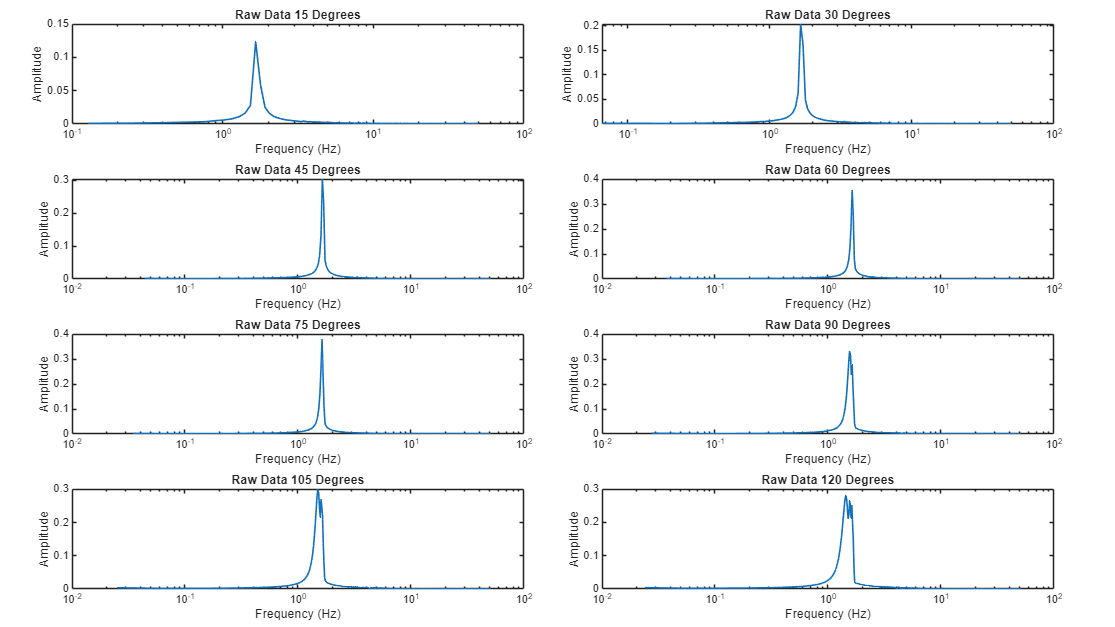

figure('Units', 'normalized', 'Position', [0, 0, 1, 1]);
tiledlayout(4, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
for i = 1:length(angles)

    % Calc sampling period and frequency
    Ts = expData(i).t(2) - expData(i).t(1);
    fs = 1/Ts;

    data_length = length(expData(i).y_id);

    % Compute the FFT
    y_fft = fft(expData(i).y_id);
    
    % Compute the two-sided spectrum P2
    P2 = abs(y_fft / data_length);
    
    % Compute the single-sided spectrum P1 based on P2
    P1 = P2(1:floor(data_length/2)+1);
    
    % Multiply by 2 to conserve energy (excluding DC and Nyquist frequencies)
    P1(2:end-1) = 2 * P1(2:end-1);
    
    % Define the frequency domain f (up to the Nyquist frequency)
    f = fs * (0:floor(data_length/2)) / data_length;
    
    nexttile;
    plot(f, P1, 'LineWidth', 1.2);
    
    title(sprintf('Raw Data %d Degrees', angles(i)));
    xlabel("Frequency (Hz)");
    ylabel("Amplitude");
    xscale('log')
end

%% Identification setup

% Estimation and validation split
idxEst = [1 3 5 7];  % 15, 45, 75, 105 degrees
idxVal = [2 4 6 8];  % 30, 60, 90, 120 degrees

% Create iddata objects
z = cell(length(angles), 1);

for i = 1:length(angles)

    y = expData(i).y_id(:);
    u = expData(i).u_id(:);

    if length(y) ~= length(u)
        error('Experiment %d has unequal y and u length.', i);
    end

    z{i} = iddata(y, u, Ts);

    z{i}.Name = sprintf('%d degrees', expData(i).initial_angle);
    z{i}.ExperimentName = sprintf('%d degrees', expData(i).initial_angle);

    z{i}.InputName = {'u'};
    z{i}.InputUnit = {'-'};

    z{i}.OutputName = {'theta'};
    z{i}.OutputUnit = {'rad'};

    z{i}.TimeUnit = 's';
    z{i}.Tstart = 0;
end

% Merge selected experiments
z_est = merge(z{idxEst});
z_val = merge(z{idxVal});

z_est.Name = 'Estimation data';
z_val.Name = 'Validation data';

%% Estimate initial guesses

[p_b2_init, p_g2_init, p_c2_init, guessInfo] = estimatePassivePendulumInitialGuessCoulomb( ...
    expData, idxEst, Ts);

fprintf('\nInitial parameter guesses:\n');


Initial parameter guesses:


fprintf('p_b2_init = %.6g  [1/s]\n', p_b2_init);

p_b2_init = 0.198199  [1/s]


fprintf('p_g2_init = %.6g  [1/s^2]\n', p_g2_init);

p_g2_init = 105.948  [1/s^2]


fprintf('p_c2_init = %.6g  [rad/s^2]\n\n', p_c2_init);

p_c2_init = 1.05948  [rad/s^2]




disp(guessInfo);

    ExperimentIndex    DominantFrequency_Hz    p_b2_guess    p_g2_guess    p_c2_guess
    _______________    ____________________    __________    __________    __________

           1                  1.6561            0.56926        108.35        1.0835  
           3                  1.6437            0.22048        106.67        1.0667  
           5                  1.6325            0.17592        105.22        1.0522  
           7                  1.4974            0.13749        88.521       0.88521  




%% Create nonlinear grey-box model

FileName = 'pendulum_rod_2_model_coulomb';

disp('Model file found at:');

Model file found at:


disp(which(FileName));

C:\School\Integration Project Systems and Control\sc_integration_project\system_identification\pendulum_rod_2_model_coulomb.m


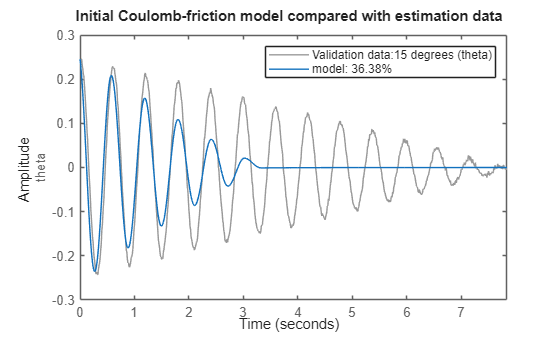


if isempty(which(FileName))
    error('MATLAB cannot find the model file "%s.m". Make sure it is on the MATLAB path.', FileName);
end

% Order = [number of outputs, number of inputs, number of states]
Order = [1 1 2];

% Parameters:
% p_b2 = viscous damping parameter
% p_g2 = gravity parameter
% p_c2 = smooth Coulomb friction parameter
Parameters = {
    p_b2_init;
    p_g2_init;
    p_c2_init
};

Ts_model = 0;  % continuous-time grey-box model

%% Initial states for estimation experiments

nEst = numel(idxEst);

theta0_est = zeros(1, nEst);
theta_dot0_est = zeros(1, nEst);

for k = 1:nEst
    i = idxEst(k);

    theta0_est(k) = expData(i).y_id(1);

    % Estimate initial velocity from first few samples.
    % This is more robust than forcing theta_dot(0) = 0.
    Nfit = min(5, length(expData(i).y_id));
    tt = expData(i).t_id(1:Nfit);
    yy = expData(i).y_id(1:Nfit);

    coeff = polyfit(tt, yy, 1);
    theta_dot0_est(k) = coeff(1);
end

if any(~isfinite(theta0_est)) || any(~isfinite(theta_dot0_est))
    error('Initial state guesses contain NaN or Inf.');
end

InitialStates = [
    theta0_est;
    theta_dot0_est
];

model = idnlgrey(FileName, Order, Parameters, InitialStates, Ts_model);

%% Name states

model = setinit(model, 'Name', {'theta'; 'theta_dot'});
model = setinit(model, 'Unit', {'rad'; 'rad/s'});

model = setinit(model, 'Minimum', {-Inf(1,nEst); -Inf(1,nEst)});
model = setinit(model, 'Maximum', { Inf(1,nEst);  Inf(1,nEst)});

% Fix theta(0), because it is measured.
% Estimate theta_dot(0), because the cut may not be exactly at a turning point.
model = setinit(model, 'Fixed', {true(1,nEst); false(1,nEst)});

%% Name parameters and set bounds

model.Parameters(1).Name = 'p_b2';
model.Parameters(1).Unit = '1/s';
model.Parameters(1).Minimum = 0;
model.Parameters(1).Maximum = Inf;
model.Parameters(1).Fixed = false;

model.Parameters(2).Name = 'p_g2';
model.Parameters(2).Unit = '1/s^2';
model.Parameters(2).Minimum = 0;
model.Parameters(2).Maximum = Inf;
model.Parameters(2).Fixed = false;

model.Parameters(3).Name = 'p_c2';
model.Parameters(3).Unit = 'rad/s^2';
model.Parameters(3).Minimum = 0;
model.Parameters(3).Maximum = Inf;
model.Parameters(3).Fixed = false;

%% Inspect initial model

figure;
compare(z_est, model);
title('Initial Coulomb-friction model compared with estimation data');


%% Estimate model

opt = nlgreyestOptions;
opt.Display = 'on';
opt.SearchOptions.MaxIterations = 150;

estimated_model = nlgreyest(z_est, model, opt);

%% Show estimated parameters

disp('Estimated model:');

Estimated model:


present(estimated_model);


estimated_model =

Continuous-time nonlinear grey-box model defined by 'pendulum_rod_2_model_coulomb' (MATLAB file):

   dx/dt = F(t, x(t), u(t), p1, ..., p3)
    y(t) = H(t, x(t), u(t), p1, ..., p3) + e(t)

 with 1 input(s), 2 state(s), 1 output(s), and 3 free parameter(s) (out of 3).

 Inputs:
    u(1)  u(t) [-]
 States:                       Initial value
    x(1)  theta(t) [rad]         xinit@exp1    0.245596   (fixed) in [-Inf, Inf]
                                 xinit@exp2    0.763433   (fixed) in [-Inf, Inf]
                                 xinit@exp1    0.327751   (fixed) in [-Inf, Inf]
                                 xinit@exp2    0.691816   (fixed) in [-Inf, Inf]
    x(2)  theta_dot(t) [rad/s]   xinit@exp1    0.327751   (estimated) in [-Inf, Inf]
                                 xinit@exp2    0.691816   (estimated) in [-Inf, Inf]
                                 xinit@exp3    0.961758   (estimated) in [-Inf, Inf]
                                 xinit@exp4   -0.672469   (


fprintf('\nEstimated parameters:\n');


Estimated parameters:


fprintf('p_b2 = %.8g  [1/s]\n',    estimated_model.Parameters(1).Value);

p_b2 = 0.067159461  [1/s]


fprintf('p_g2 = %.8g  [1/s^2]\n',  estimated_model.Parameters(2).Value);

p_g2 = 112.02375  [1/s^2]


fprintf('p_c2 = %.8g  [rad/s^2]\n', estimated_model.Parameters(3).Value);

p_c2 = 0.24803439  [rad/s^2]


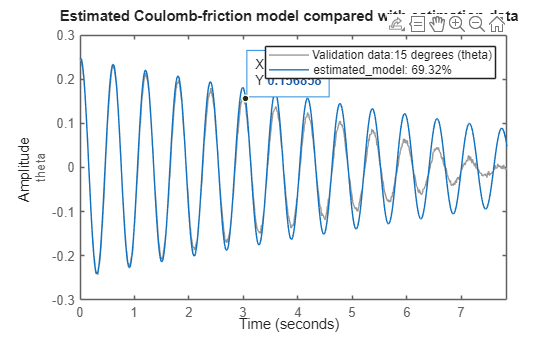


%% Compare on estimation data

figure;
compare(z_est, estimated_model);
title('Estimated Coulomb-friction model compared with estimation data');

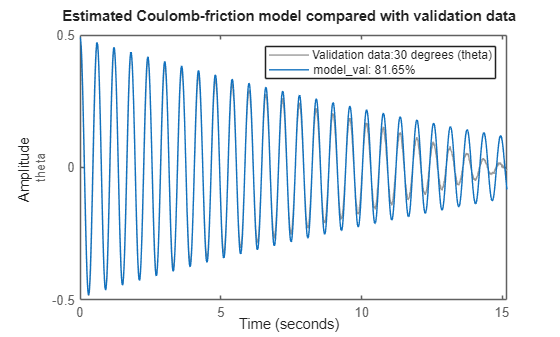


%% Build separate validation model

nVal = numel(idxVal);

theta0_val = zeros(1, nVal);
theta_dot0_val = zeros(1, nVal);

for k = 1:nVal
    i = idxVal(k);

    theta0_val(k) = expData(i).y_id(1);

    Nfit = min(5, length(expData(i).y_id));
    tt = expData(i).t_id(1:Nfit);
    yy = expData(i).y_id(1:Nfit);

    coeff = polyfit(tt, yy, 1);
    theta_dot0_val(k) = coeff(1);
end

InitialStates_val = [
    theta0_val;
    theta_dot0_val
];

Parameters_val = {
    estimated_model.Parameters(1).Value;
    estimated_model.Parameters(2).Value;
    estimated_model.Parameters(3).Value
};

model_val = idnlgrey(FileName, Order, Parameters_val, InitialStates_val, Ts_model);

%% Name validation model states

model_val = setinit(model_val, 'Name', {'theta'; 'theta_dot'});
model_val = setinit(model_val, 'Unit', {'rad'; 'rad/s'});

model_val = setinit(model_val, 'Minimum', {-Inf(1,nVal); -Inf(1,nVal)});
model_val = setinit(model_val, 'Maximum', { Inf(1,nVal);  Inf(1,nVal)});

% For validation, keep measured angle fixed and allow velocity uncertainty.
model_val = setinit(model_val, 'Fixed', {true(1,nVal); false(1,nVal)});

%% Name validation model parameters and fix them

model_val.Parameters(1).Name = 'p_b2';
model_val.Parameters(1).Unit = '1/s';
model_val.Parameters(1).Minimum = 0;
model_val.Parameters(1).Maximum = Inf;
model_val.Parameters(1).Fixed = true;

model_val.Parameters(2).Name = 'p_g2';
model_val.Parameters(2).Unit = '1/s^2';
model_val.Parameters(2).Minimum = 0;
model_val.Parameters(2).Maximum = Inf;
model_val.Parameters(2).Fixed = true;

model_val.Parameters(3).Name = 'p_c2';
model_val.Parameters(3).Unit = 'rad/s^2';
model_val.Parameters(3).Minimum = 0;
model_val.Parameters(3).Maximum = Inf;
model_val.Parameters(3).Fixed = true;

%% Compare on validation data

figure;
compare(z_val, model_val);
title('Estimated Coulomb-friction model compared with validation data');

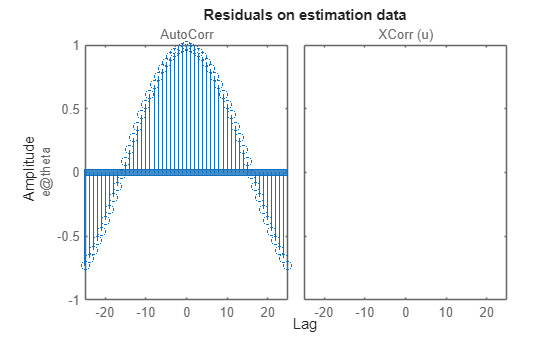


%% Residual analysis

figure;
resid(z_est, estimated_model);
title('Residuals on estimation data');

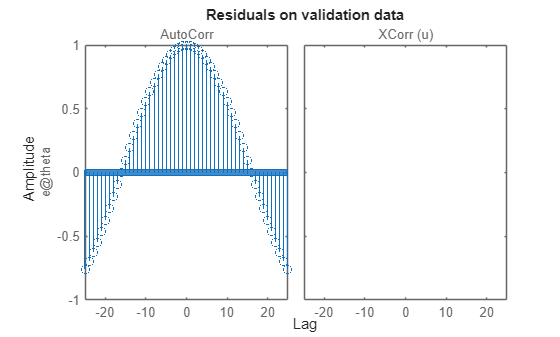


figure;
resid(z_val, model_val);
title('Residuals on validation data');

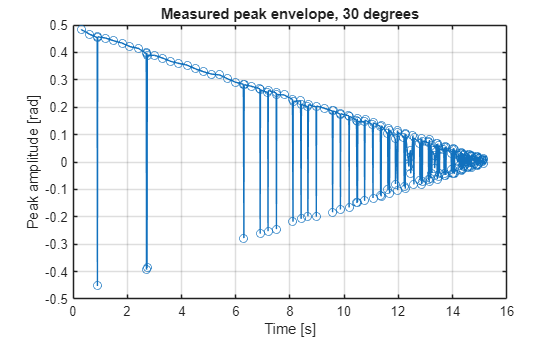

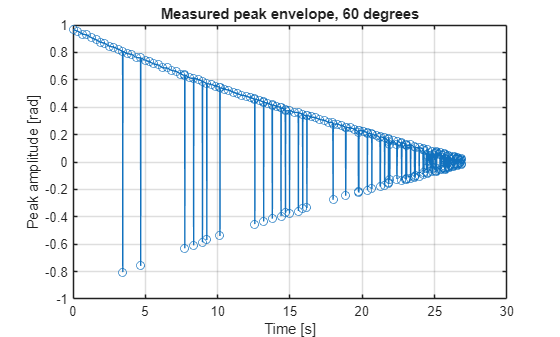

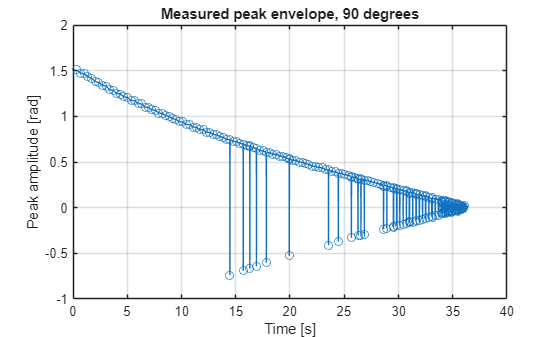

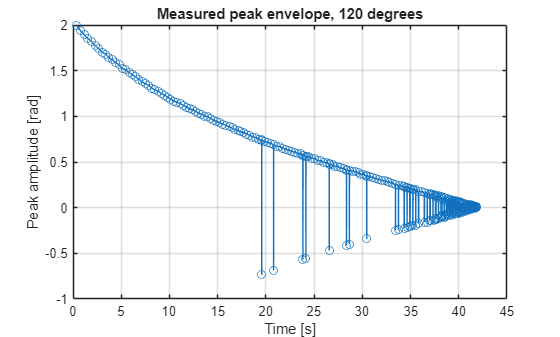


%% Compare viscous-only behaviour against Coulomb model envelope, optional visual check

for ii = 1:numel(idxVal)

    i = idxVal(ii);

    t = expData(i).t_id(:);
    y = expData(i).y_id(:);

    [pkMax, locMax] = findpeaks(y, t);
    [pkMin, locMin] = findpeaks(-y, t);

    amp = [pkMax; pkMin];
    tpk = [locMax; locMin];

    [tpk, sortIdx] = sort(tpk);
    amp = amp(sortIdx);

    figure;
    plot(tpk, amp, 'o-');
    xlabel('Time [s]');
    ylabel('Peak amplitude [rad]');
    title(sprintf('Measured peak envelope, %d degrees', angles(i)));
    grid on;
end


%% Local function: initial guesses

function [p_b2_init, p_g2_init, p_c2_init, infoTable] = estimatePassivePendulumInitialGuessCoulomb(expData, idxEst, Ts)
%ESTIMATEPASSIVEPENDULUMINITIALGUESSCOULOMB
% Estimates rough initial guesses for:
%
%   theta_ddot = -p_b2 theta_dot - p_c2 tanh(theta_dot/eps_v) - p_g2 sin(theta)
%
% The gravity and viscous damping guesses are based on a small-oscillation
% approximation. The Coulomb term is initialized conservatively.

n = numel(idxEst);

f_peak_all = nan(n,1);
p_b2_all = nan(n,1);
p_g2_all = nan(n,1);
p_c2_all = nan(n,1);

for k = 1:n

    i = idxEst(k);

    t = expData(i).t_id(:);
    y = expData(i).y_id(:);

    y_centered = y - mean(y);

    N = length(y_centered);
    fs = 1/Ts;

    %% Dominant frequency from FFT

    Y = fft(y_centered);

    P2 = abs(Y/N);
    P1 = P2(1:floor(N/2)+1);
    P1(2:end-1) = 2*P1(2:end-1);

    f = fs*(0:floor(N/2))'/N;

    valid = f > 0.05 & f < 20;

    if ~any(valid)
        error('No valid frequency range found for experiment index %d.', i);
    end

    f_valid = f(valid);
    P_valid = P1(valid);

    [~, loc] = max(P_valid);
    f_peak = f_valid(loc);

    omega_d = 2*pi*f_peak;

    %% Damping estimate from amplitude envelope

    y_abs = abs(y_centered);

    minPeakDistance = max(1, round(0.25*(1/f_peak)/Ts));

    try
        [pk, locs] = findpeaks(y_abs, ...
            'MinPeakDistance', minPeakDistance, ...
            'MinPeakProminence', 0.01*max(y_abs));
    catch
        [pk, locs] = findpeaks(y_abs, ...
            'MinPeakDistance', minPeakDistance);
    end

    if ~isempty(pk)
        keep = pk > 0.05*max(pk);
        pk = pk(keep);
        locs = locs(keep);
    end

    if numel(pk) >= 3
        t_peaks = t(locs);

        % Viscous damping approximation:
        % log(amplitude) = c - p_b2/2 * t
        coeff = polyfit(t_peaks, log(pk), 1);
        p_b2 = max(0, -2*coeff(1));
    else
        p_b2 = 0.05*omega_d;
    end

    %% Gravity estimate

    omega0_squared = omega_d^2 + (p_b2/2)^2;
    p_g2 = max(omega0_squared, 1e-6);

    %% Coulomb friction initial guess

    % Conservative initial Coulomb term.
    % This should be small enough that it does not dominate immediately,
    % but nonzero so that the optimizer can use it.
    p_c2 = 0.01*p_g2;

    f_peak_all(k) = f_peak;
    p_b2_all(k) = p_b2;
    p_g2_all(k) = p_g2;
    p_c2_all(k) = p_c2;
end

p_b2_init = median(p_b2_all, 'omitnan');
p_g2_init = median(p_g2_all, 'omitnan');
p_c2_init = median(p_c2_all, 'omitnan');

p_b2_init = max(p_b2_init, 1e-6);
p_g2_init = max(p_g2_init, 1e-6);
p_c2_init = max(p_c2_init, 1e-8);

infoTable = table(idxEst(:), f_peak_all, p_b2_all, p_g2_all, p_c2_all, ...
    'VariableNames', {'ExperimentIndex', 'DominantFrequency_Hz', ...
    'p_b2_guess', 'p_g2_guess', 'p_c2_guess'});

end